# Examine Dual-List Session using Temporal Field Bayes - Behavior Summary

fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];
% fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);


## Compile Dual List Behavior

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Hold Durations
        trialHoldDurs = cell(length(mlb.odrVect), 1, length(fileDirs));
        % TransMat
        transMatTrialMean = zeros(length(mlb.odrVect),mlb.seqLength,2);
        transMatAniMean = zeros(length(mlb.odrVect),mlb.seqLength,length(fileDirs));
        % SMI Lag
        lagAccTrialMean = zeros(size(mlb.lagAccVect));
        lagAccAniMean = nan(2,length(mlb.lagVect),length(fileDirs));
        % SMI
        smi = nan(length(fileDirs),2);
        smiByPos = nan(2, mlb.seqLength,length(fileDirs));
        smiByOdr = nan(2, mlb.seqLength, length(fileDirs));        
    end
    mlb.SummarizeSessionBehavior;
    % TransMat Acc
    transMatTrialMean = transMatTrialMean+mlb.transMatPerf;
    transMatAniMean(:,:,ani) = mlb.transMatPerf(:,:,1)./sum(mlb.transMatPerf,3);
    % Lag Acc
    lagAccTrialMean = lagAccTrialMean + mlb.lagAccVect;
    lagAccAniMean(:,:,ani) = mlb.lagAccVect(:,:,1)./sum(mlb.lagAccVect,3);
    % SMI
    smi(ani,:) = mlb.smi;
%     smi(ani,:) = mlb.smiSFP;
    smiByPos(:,:,ani) = mlb.smiByPos;
    smiByOdr(:,:,ani) = mlb.smiByOdr;  
    
end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


toc

Elapsed time is 12.598308 seconds.


## Plot TransMat By List

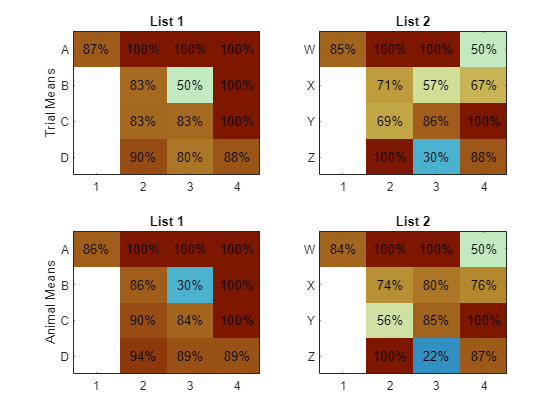

transMatPerf = transMatTrialMean(:,:,1)./sum(transMatTrialMean,3);
listLog = mlb.odrVect<10;
figure; 
subplot(2,2,1)
l1Tmat = transMatPerf(listLog,:);
imagesc(l1Tmat, [0 1]);
set(gca, 'ytick',1:mlb.seqLength, 'yticklabel', mlb.Rosetta(1:mlb.seqLength), 'xtick',1:mlb.seqLength);
for o = 1:mlb.seqLength
    for p = 1:mlb.seqLength
        if ~isnan(l1Tmat(o,p))
            text(p,o,sprintf('%.00f%%',l1Tmat(o,p)*100),'HorizontalAlignment','center','VerticalAlignment','middle');
        end
    end
end
title('List 1');
ylabel('Trial Means');
colormap(cMapNanW);
subplot(2,2,2)
l2Tmat = transMatPerf(~listLog,:);
imagesc(l2Tmat, [0 1]);
set(gca, 'ytick',1:mlb.seqLength, 'yticklabel', mlb.Rosetta(end-mlb.seqLength+1:end), 'xtick',1:mlb.seqLength);
for o = 1:mlb.seqLength
    for p = 1:mlb.seqLength
        if ~isnan(l2Tmat(o,p))
            text(p,o,sprintf('%.00f%%',l2Tmat(o,p)*100),'HorizontalAlignment','center','VerticalAlignment','middle');
        end
    end
end
title('List 2');
colormap(cMapNanW);

subplot(2,2,3)
l1Tmat = mean(transMatAniMean(listLog,:,:),3,'omitnan');
imagesc(l1Tmat, [0 1]);
set(gca, 'ytick',1:mlb.seqLength, 'yticklabel', mlb.Rosetta(1:mlb.seqLength), 'xtick',1:mlb.seqLength);
for o = 1:mlb.seqLength
    for p = 1:mlb.seqLength
        if ~isnan(l1Tmat(o,p))
            text(p,o,sprintf('%.00f%%',l1Tmat(o,p)*100),'HorizontalAlignment','center','VerticalAlignment','middle');
        end
    end
end
title('List 1');
ylabel('Animal Means');
colormap(cMapNanW);
subplot(2,2,4)
l2Tmat = mean(transMatAniMean(~listLog,:,:),3,'omitnan');
imagesc(l2Tmat, [0 1]);
set(gca, 'ytick',1:mlb.seqLength, 'yticklabel', mlb.Rosetta(end-mlb.seqLength+1:end), 'xtick',1:mlb.seqLength);
for o = 1:mlb.seqLength
    for p = 1:mlb.seqLength
        if ~isnan(l2Tmat(o,p))
            text(p,o,sprintf('%.00f%%',l2Tmat(o,p)*100),'HorizontalAlignment','center','VerticalAlignment','middle');
        end
    end
end
title('List 2');
colormap(cMapNanW);

## Plot LagVect Accuracy by List

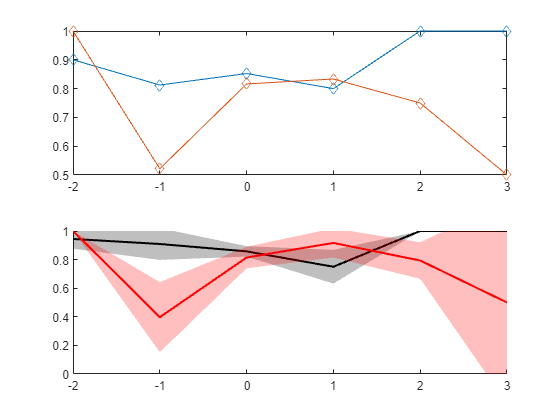

lagTrialPerf = lagAccTrialMean(:,:,1)./sum(lagAccTrialMean,3);
figure; 
subplot(2,1,1);
plot(mlb.lagVect, lagTrialPerf','-d');
subplot(2,1,2)
mlb.PlotMeanVarLine(mlb.lagVect, lagAccAniMean(1,:,:),3,0, 'k');
set(gca, 'ylim', [0 1]);
mlb.PlotMeanVarLine(mlb.lagVect, lagAccAniMean(2,:,:),3,0, 'r');
set(gca, 'ylim', [0 1]);

## Analyze Overt Performance (SMI)

listID = repmat(1:2,[length(fileDirs),1]);
[h,p,ci,stats] = ttest(smi(:), listID(:))

h = 1

p = 0.0109

ci =    -1.6834
   -0.3551


stats = struct with fields:
    tstat: -3.9450
       df: 5
       sd: 0.6329


aniID = repmat((1:3)',[1,2]);
[h,p,ci,stats] = ttest(smi(:), aniID(:))

h = 1

p = 0.0049

ci =    -2.3316
   -0.7070


stats = struct with fields:
    tstat: -4.8078
       df: 5
       sd: 0.7740


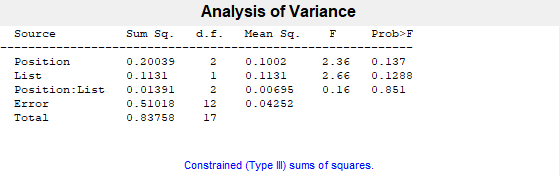


posOdrID = repmat(1:4, [2,1,length(fileDirs)]);
listID = repmat((1:2)', [1,mlb.seqLength, length(fileDirs)]);
[p,tbl,stats] = anovan(smiByPos(:), {posOdrID(:),listID(:)}, 'model', 'full', 'varnames', {'Position', 'List'});

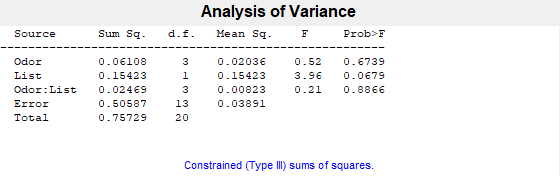

[p,tbl,stats] = anovan(smiByOdr(:), {posOdrID(:), listID(:)}, 'model', 'full', 'varnames', {'Odor', 'List'});